# Blackjack Policy Performance Evaluation Examples.

This demonstration is intended to illustrate how to use the `blackjack_evaluate_policy` function which is included with this repository.

## Create an Agent - Define a Policy

The RL agent is defined by a *policy* which generates an action based on the current obseration.

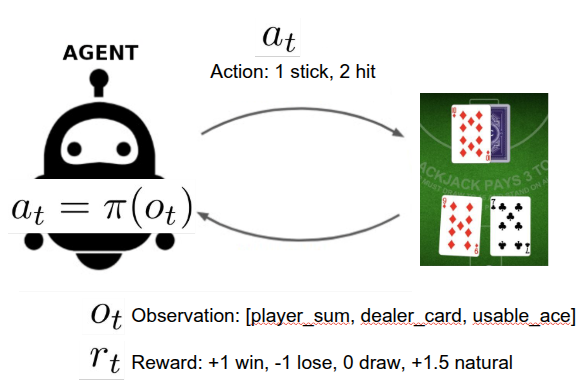

To use the `blackjack_evaluate_policy` function to evaluate the policy, we must create a ***function handle ***to a function that implements the policy.

## Example 1: Random Policy

We could create an agent by defining a random policy...

function action = policy_rand(observation)
    action = randi([1, 2]); % Randomly choose action 1 or 2
end

We can then evaluate this policy based on playing N = 1000 games.

[rewards, mu, conf95] = blackjack_evaluate_policy(@policy_rand, 1000);

Mean reward: -0.325, We are 95% confident that the mean reward is between -0.383 and -0.267


What happens as we increase/decreae the value of `N `?

## Example 2: Q-Learning Policy

The result of our q-learning example is to generate a q-table, $Q(S,A)$, that approximates the optimal optimal value table is known, $Q^*(S,A)$.  The corresonding policy is simply to choose the action (hit or stand) that maximizes the q-table value. 

$\pi(S) = A  = \arg\max_{A} Q(S, A)
$.

To implement this policy we need a q-table.   A q-table is generated by the the Blackjack Q-Learning example.   We saved the resulting `qtable` variable as the local `.mat` data file.  We can load that `qtable` variable...

load("blackjack_qlearning_qtable.mat")
whos("qtable")

  Name        Size             Bytes  Class         Attributes

  qtable      1x1             115344  dictionary              



To create a function to implements our qtable policy, we need to do two things.....

### Q-Learning Policy - Q-Table Input

function action = policy_qlearning(observation, q_table)
    % Return the action to maximize value for the givein observation.
    qc = q_table({observation});
    [maxval, maxi] = max(qc{1});
    action = maxi;
end  

This policy function needs **both** the current observation and the static q-table as input arguments, but the  `blackjack_evaluate_policy` function requires that the `policy_fun` handle only have a single input of the observation.  One way to solve this problem is to use an anonymous function as a *wrapper...*

### Wrapped Q-Learning Policy

The `policy_fun` is a handle to a a function that has `obs` as a single input argument and the calls our `policy_qlearning` function with the argument `obs` and the varaible `qtable` as inputs.

policy_fun = @(obs) policy_qlearning(obs, qtable);

Now we can pass this function handle to the evaluation function.

[rewards, mu, conf95] = blackjack_evaluate_policy(policy_fun, 1000);

Mean reward: -0.036, We are 95% confident that the mean reward is between -0.096 and 0.024
